# GQ 2 Modèle DCC et Granger Test

clc;
clear,
data = readtable('inefficiency.xlsx');
dates = data(:,1); % date
data = data(:,2:end); % inefficiency
varNames = data.Properties.VariableNames;

### Test d'augmented Dickey Fuller

adfLags = 9;
[adfStats, adfP] = performADFTest(data, adfLags);

adfResults = table( ...
    varNames(:), ...
    adfStats(:), ...
    adfP(:), ...
    repmat(adfLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

adfResults = 2×4 table
    MarketIndex    Statistic    pValue     Lags
    ___________    _________    _______    ____

    {'ftsemib'}     -1.3718     0.15825     9  
    {'ftse100'}     -1.6299     0.09729     9  


data_diff = diff(data);
adfLags = 9;
[adfStats, adfP] = performADFTest(data_diff, adfLags);


adfResults = table( ...
    varNames(:), ...
    adfStats(:), ...
    adfP(:), ...
    repmat(adfLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

adfResults = 2×4 table
    MarketIndex    Statistic    pValue    Lags
    ___________    _________    ______    ____

    {'ftsemib'}     -16.692     0.001      9  
    {'ftse100'}     -12.281     0.001      9  


## Test de présence d'effet ARCH

archLags = 12;
[archStats, archP] = performARCHTest(data_diff, archLags);

archResults = table( ...
    varNames(:), ...
    archStats(:), ...
    archP(:), ...
    repmat(archLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

archResults = 2×4 table
    MarketIndex    Statistic    pValue    Lags
    ___________    _________    ______    ____

    {'ftsemib'}     326.42        0        12 
    {'ftse100'}     253.61        0        12 


## GARCH

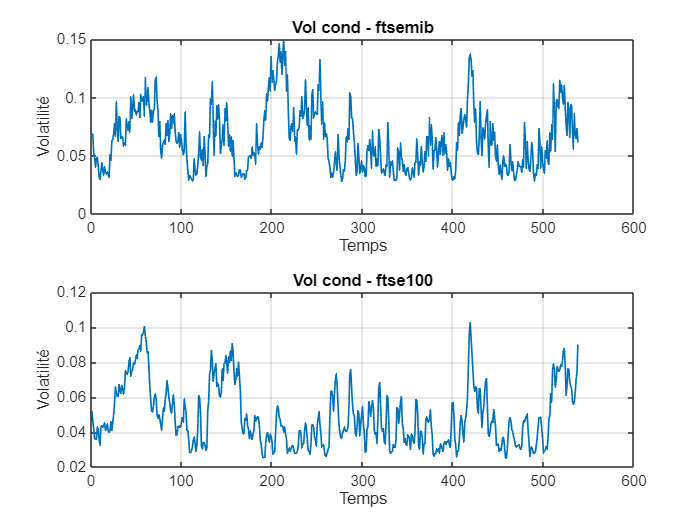

% Supposons que "I_matrix" soit une table ou une matrice de séries
[condVols, residuals, aics, pqs] = estimateGARCH(data_diff, 10, 10);


% ========================
% Plot des volatilities conditionnelles
% ========================
figure('Name', 'Volatilités Conditionnelles');
tiledlayout('flow');

[T, N] = size(condVols);
for i = 1:N
    nexttile;
    plot(condVols(:, i), 'LineWidth', 1);
    title(['Vol cond - ', varNames{i}], 'Interpreter', 'none');
    xlabel('Temps');
    ylabel('Volatilité');
    grid on;
end

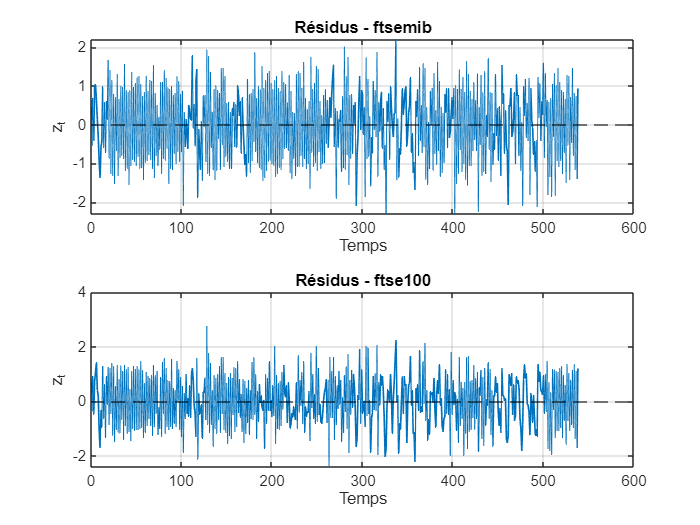

figure('Name', 'Résidus Standardisés');
tiledlayout('flow');

for i = 1:N
    nexttile;
    plot(residuals(:, i), 'LineWidth', 1);
    title(['Résidus - ', varNames{i}], 'Interpreter', 'none');
    xlabel('Temps');
    ylabel('z_t');
    yline(0, '--k');
    grid on;
end

## ARCH on resids

residuals = array2table(residuals, 'VariableNames',varNames);
condVols = array2table(condVols, 'VariableNames',varNames);
[archStats, archP] = performARCHTest(residuals , archLags);

archResults = table( ...
    varNames(:), ...
    archStats(:), ...
    archP(:), ...
    repmat(archLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

archResults = 2×4 table
    MarketIndex    Statistic     pValue      Lags
    ___________    _________    _________    ____

    {'ftsemib'}     30.815      0.0021023     12 
    {'ftse100'}     20.987       0.050565     12 



____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.170837e+03    0.000e+00    2.946e+02
    1       8    1.165219e+03    0.000e+00    2.768e+02    2.505e-01
    2      13    1.160108e+03    0.000e+00    1.765e+02    1.105e-01
    3    

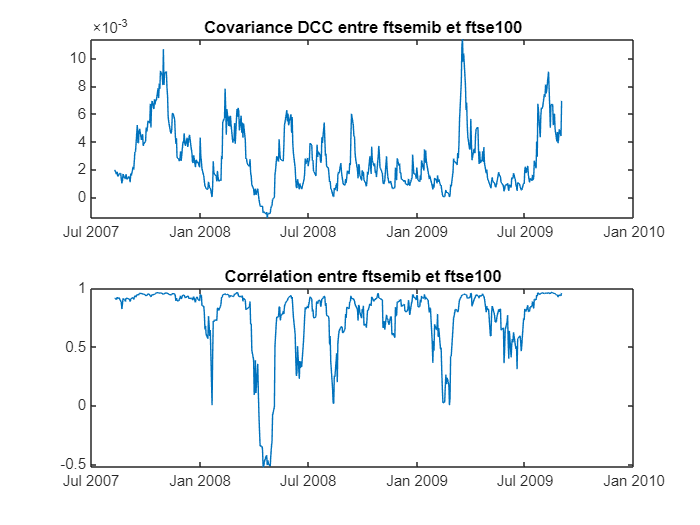

% Paramètres du modèle DCC
M = 1;
L = 0;
N = 1;
P = 1;
O = 0; % Mettre à 1 si présence d'un effet d'asymétrie
Q = 1;
data_dcc = data_diff;
numCols = size(data_dcc, 2);
for i = 1:numCols
    for j = i+1:numCols
        % Extract the pair of columns as vectors
        data1 = table2array(data_dcc(:, i));
        data2 = table2array(data_dcc(:, j));
        
        colName1 = data.Properties.VariableNames{i};
        colName2 = data.Properties.VariableNames{j};

        % Compute DCC
        [cov_dcc, corr_dcc] = computeDCC(data1, data2, M, L, N, P, O, Q);

        % Create a new figure for each pair
        figure;

        % Plot the results
        subplot(2, 1, 1);
        plot(table2array(dates(2:end,:)), cov_dcc);
        title(['Covariance DCC entre ', colName1, ' et ', colName2]);

        subplot(2, 1, 2);
        plot(table2array(dates(2:end,:)), corr_dcc);
        title(['Corrélation entre ', colName1, ' et ', colName2]);
    end
end

## Granger Causality Test + VAR

[result_VAR, result_Granger] = estimate_VAR(data_diff(:,1), data_diff(:,2), P)

data1 is a table, converting to array.
data2 is a table, converting to array.


Error using gctest (line 162)
The value of 'Y2' is invalid. Expected input to be one of these types:

double

Error in estimate_VAR (line 62)
    [h12, p12, stat12] = gctest([data1, data2], 'YIdx', 1, 'XIdx', 2, 'NumLags', p);

license('test', 'Econometri

ans = 1

cs_Toolbox')

data = randn(100, 2); % 100 observations, 2 variables

% Estimer un VAR(2)
p = 2;
model = varm(2, p);
EstMdl = estimate(model, data);

% Effectuer le test de causalité de Granger
h = gctest_perso(data(:,1), data(:,2));

% Afficher les résultats
fprintf('Hypothèse nulle rejetée ? %d\n', h);

Hypothèse nulle rejetée ? 0


fprintf('p-value = %f\n', pVal);

Unrecognized function or variable 'pVal'.

fprintf('Statistique de test = %f\n', stat);